clc,clear,close all
global hstep
global Element
global Center
global M2

设置方程

% u0 = @(x) 1/4+1/2*sin(pi*x);   % 初值
u0 = @(x) sin(pi*x);   % 初值
left = -1;              % 求解区间
right = 1;              % 求解区间
time = 0.1;             % 时间
num = 10;               % 区间数量

分配内存

Num = num+2;                        % 周期边界条件，左右各加一个区间后，区间数量
delta_t = 0.1*(right-left)/num;     % 时间步长
hstep = (right-left)/num;           % 每个区间的长度，这里设置成等长。
Element_l = left-hstep:hstep:right; % 每个区间的左边界，大小为 1xNum
Element_r = left:hstep:right+hstep; % 每个区间的右边界，大小为 1xNum
Element = [Element_l',Element_r'];  % 每个区间的左右边界，大小为 Numx2
Center = mean(Element,2);           % 每个区间的中心点，大小为 Numx1
M2 = 9;

初始化

U = Uinitial(u0,num);

龙格库塔迭代

U = SetBoundary(U);

计算在Center点的数值解和解析解

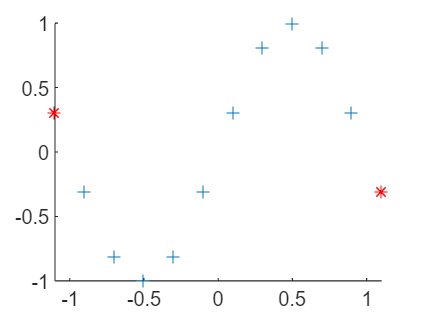

$$ans = 0.0$$

xx = Center;
yy = zeros(Num,1);
for i = 1:Num
    yy(i) = u(U,i,xx(i));
end
figure
hold on
plot(xx(2:num+1),yy(2:num+1),'+')
plot(xx(1),yy(1),'r*')
plot(xx(end),yy(end),'r*')
hold off